%-----------------------%
% Opgaver til kapitel 5 %
%-----------------------%

$$ans = -213.64215120060839537051080171602$$

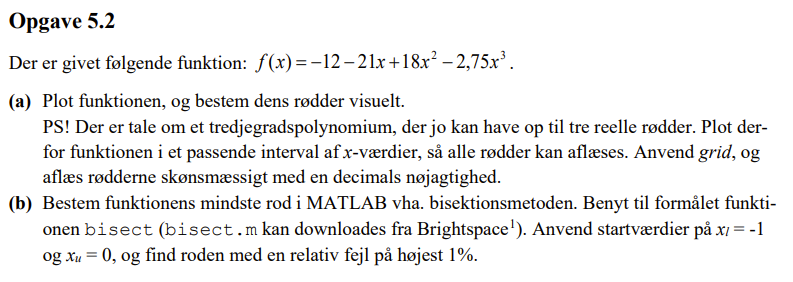

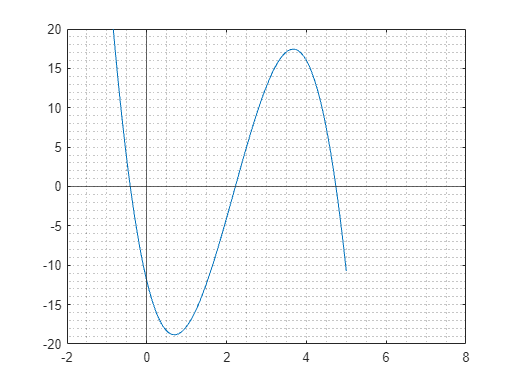

f = @(x) -12 -21.*x + 18.*x.^2 - 2.75.*x.^3;

fplot(f, [-5,5]), yline(0), xline(0), grid("minor")

xlim([-2,8]), ylim([-20, 20])



x1 = -1; x2 = 2;    x3 = 4.5;
xu1 = 0; xu2 = 2.5;  xu3 = 5;

root1 = bisect(f, x1, xu1, 1);

root =   -0.417968750000000


fx =    0.122705712914467


ea =    0.934579439252336


iter =      8


root2 = bisect(f, x2, xu2, 1);

root =    2.234375000000000


fx =    0.265742301940918


ea =    0.699300699300699


iter =      5


root3 = bisect(f, x3, xu3, 1);

root =    4.718750000000000


fx =    0.761131286621094


ea =    0.662251655629139


iter =      4


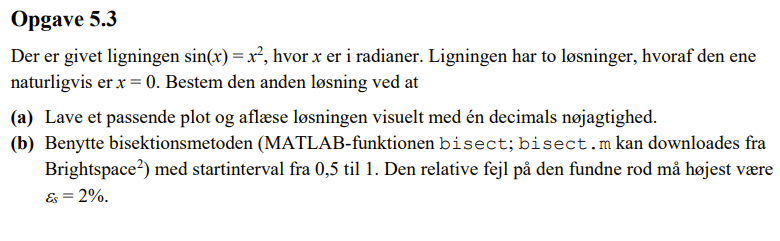

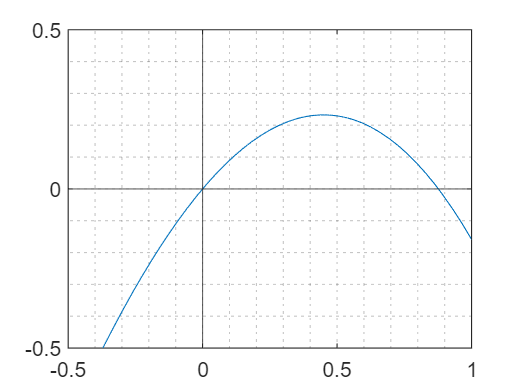

clc
clear

f = @(x) sin(x) - x.^2;

fplot(f, [-5,5]), yline(0), xline(0), grid("minor")
xlim([-0.5,1]), ylim([-0.5, 0.5])


x1 = 0.5;   xu1 = 1;    es = 2;

root1 = bisect(f, x1, xu1, es);

root = 0.8906

fx = -0.0157

ea = 1.7544

iter = 5

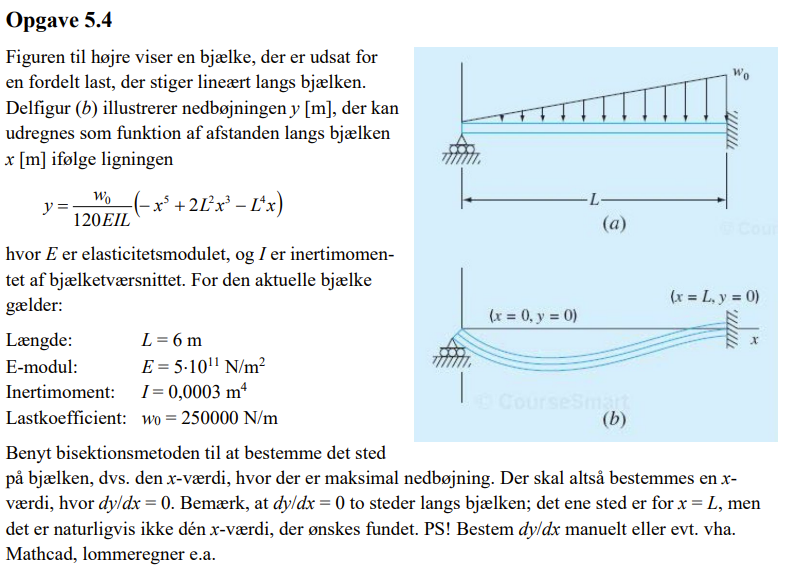

clc
clear

L = 6;  E = 5e11;   I = 0.0003; wo = 250000;

syms x

f = wo/(120*E*I*L) * (-x^5 + 2*L^2*x^3 - L^4*x);

f2 = matlabFunction(diff(f, x))

f2 = function_handle with value:
    @(x)x.^2.*5.0e-4-x.^4.*1.157407407407407e-5-3.0e-3


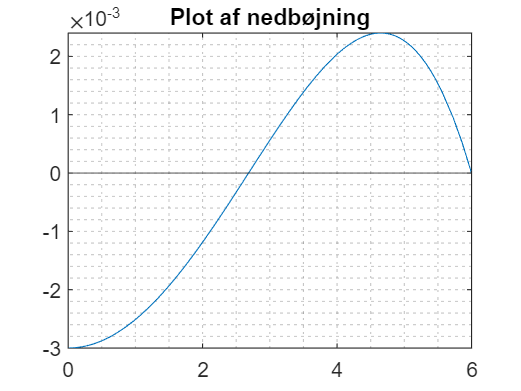


fplot(f2), xlim([0, L]), grid("minor"), xline(0), yline(0)
title("Plot af nedbøjning")


disp("Herunder er roden og andet info")

Herunder er roden og andet info


root = bisect(f2, 2, 3, 0.001);

root = 2.6833

fx = -1.4772e-08

ea = 5.6866e-04

iter = 16


disp("Her er nednøjningen i meter")

Her er nednøjningen i meter


vpa(subs(f, x, root), 4)

$$ans = -0.005152$$